clc
clear
close all
s=tf('s');
approximateSys=0.3981*(-s/5+1)/(s/5+1)/s/(s^2/25+2/5*0.09752*s+1);
%---------------------part C 1-------------------%
close all
figure
C=db2mag(18);

%----------lead1 start-------------%
C1=LeadGenerator(8,60,10);
C2=LeadGenerator(0.9,60,10);
C3=LeadGenerator(db2mag(7.657),30,4.952)


C3 =
 
  0.4876 s + 1.394
  ----------------
    0.1166 s + 1
 
Continuous-time transfer function.



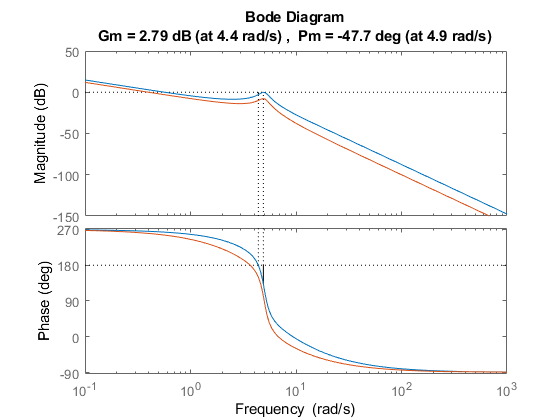

%------------lead1 end-----------%

%---------lag start-------------%
% K_cL1=db2mag(0.1);
% K1L_1=K_cL1-1;
% aL1=1/K_cL1;
% epsilon1=1;
% w_mL1=10;
% TL1=1/w_mL1*sqrt((K1L_1/epsilon1)^2-1);
% C2=K_cL1*(aL1*TL1*s+1)/(TL1*s+1);

%--------------- lag end-------------------%
C=db2mag(5);
sys=C3*approximateSys;
margin(sys)
hold on
bode(approximateSys)

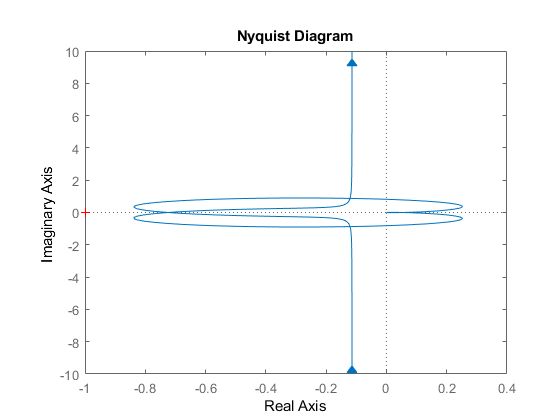

% hold on
% bode(C1)
figure
nyquist(sys)

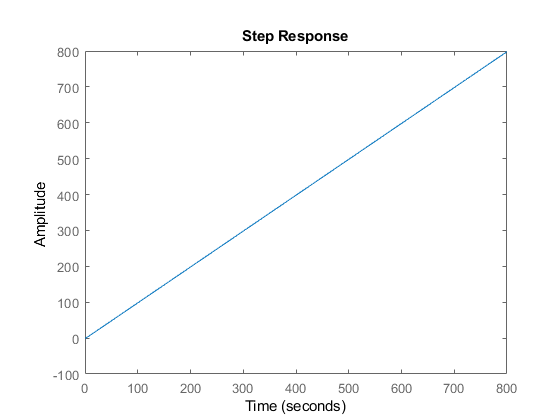

figure
step(feedback(sys,1)/s)